# E4

# Binarització de la imatge

#### Threshold global (manual)

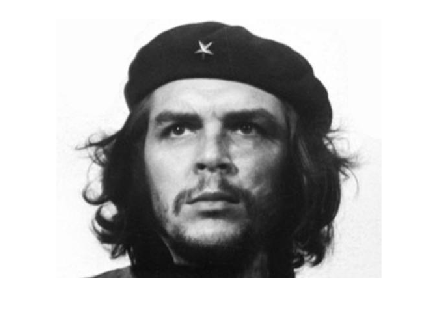

I = rgb2gray(imread('Che.jpg'));
imshow(I);

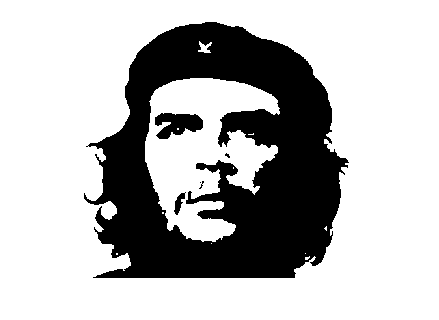

BW = I > 110;
imshow(BW);

#### Binarització a dos nivells

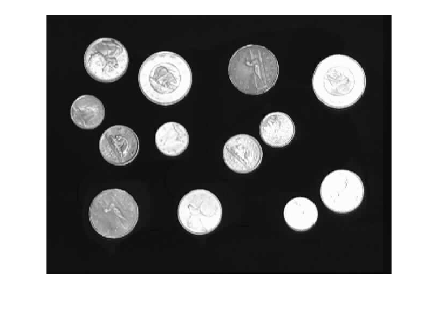

I = imread('money.tif');
imshow(I);

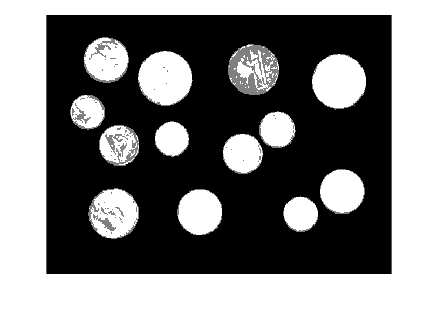


H = I > 150;
L = I < 50;
M = L == H; % a zero tant en L com en H

R = 2*H + M + 0*L;
imshow(R,[]);

#### Binarització per àrea

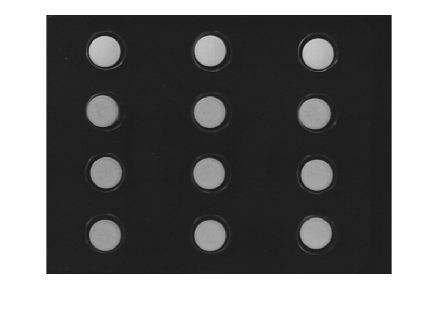

I = rgb2gray(imread('Blispac2.tif'));
imshow(I);

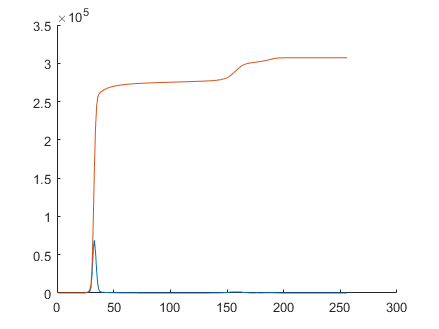

d = 95-38;
area_pastilla = pi * (d/2)^2;
area = 12 * area_pastilla;

h = imhist(I);
hacum = cumsum(h); % histograma acomulat
figure
hold on
plot (h)
plot(hacum)
hold off


[f c] = size(I);

for i = 1:size(hacum)
    if (hacum(i) > (f*c-area)) 
        llindar = i
        break;
    end
end

llindar = 128

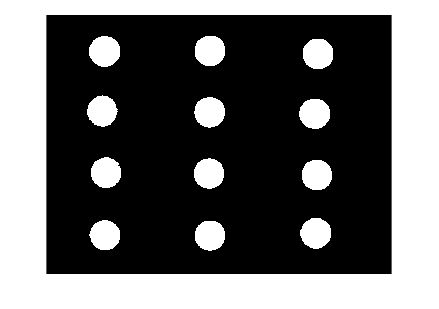


J = I > llindar;
imshow(J);


hb = hacum > (f*c-area);
llindar = find(hb,1);

I = I > llindar;
imshow(I);

#### Otsu thresholding

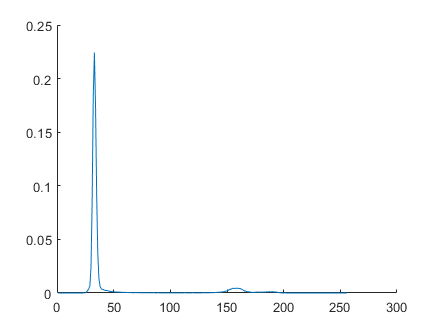

I = rgb2gray(imread('Blispac2.tif'));
h = imhist(I);
[f c] = size(I);
p = h/(f*c);

figure
hold on
plot(p)
hold off

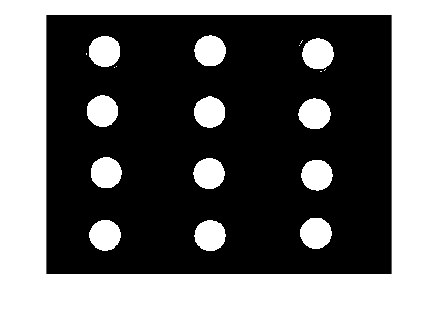


m = (0:255).*p(1:256)';
maxv = 0;
maxt = 0;
for t = 1:256
    w0 = sum(p(1:t));
    w1 = 1 - w0;
    nyu0 = (sum(m(1:t)))/w0;
    nyu1 = (sum(m(t:256)))/w1;
    ab = w0*w1*(nyu0-nyu1)^2;
    if (ab > maxv) 
        maxt = t;
        maxv = ab;
    end
end
llindar = maxt;
BW = I > llindar;
imshow(BW);

### Labelling

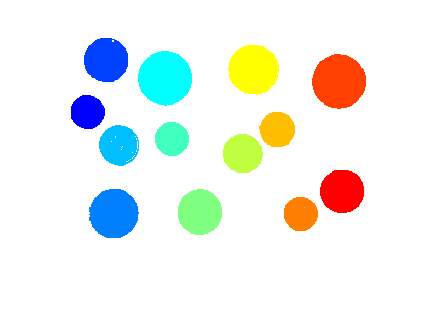

I = imread('money.tif');
BW = I > 100;
L = bwlabel(BW);
RGB = label2rgb(L);
imshow(RGB);

C = bwconncomp(BW);
CBW = BW;
CBW(C.PixelIdxList{1}) = 0

CBW = 480×640 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

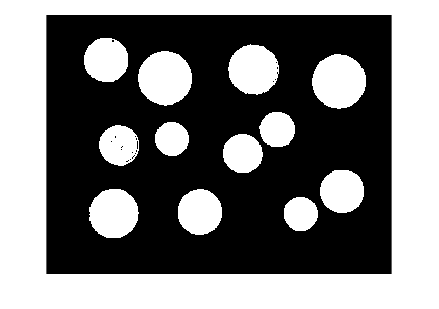

imshow(CBW);

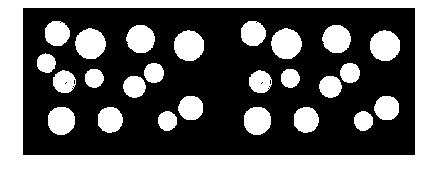

montage({BW,CBW});

#### Eliminem la moneda amb més àrea = més píxels

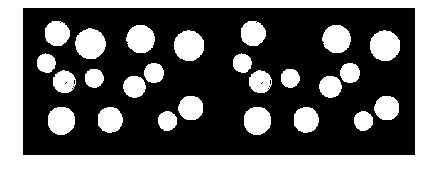

npixels = cellfun(@numel,C.PixelIdxList);
[valormaxim, posicio] = max(npixels);
CBW = BW;
CBW(C.PixelIdxList{posicio}) = 0;
montage({BW,CBW});

#### Efectes visuals

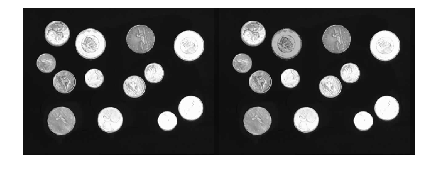

IC = I;
IC(C.PixelIdxList{posicio}) = I(C.PixelIdxList{posicio}) - 64; % = 0 (per esborrar)
montage({I,IC});

#### Binaritzat segona part

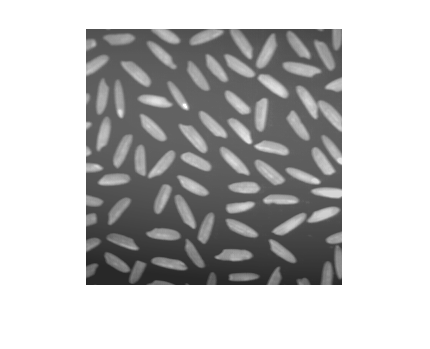

I = imread('arros.tif');
imshow(I);

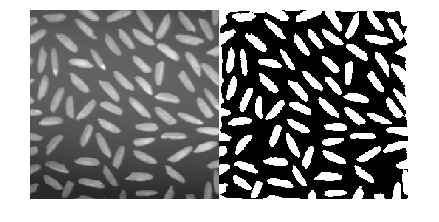

window = [30 30];
M = colfilt(I,window,'sliding',@mean);
k = 16;
BW = I > M + k; % sumem k per evitar taques al background
montage({I,BW});

% (objecte clar) BW = I > M + k
% (objecte fosc) Bw = I < M - k

#### Exercici 1

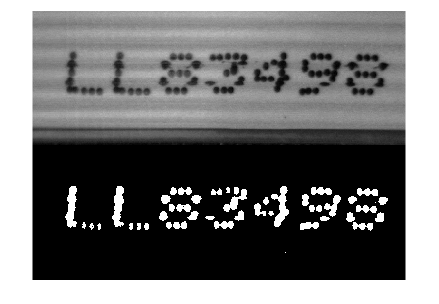

I = imread('FlatCable1.tif');
%imshow(I);

window = [1 100];
M = colfilt(I,window,'sliding',@mean);
k = 25;
BW = I < M - k; % restem k per evitar taques al background
montage({I,BW});

#### Exercici 2

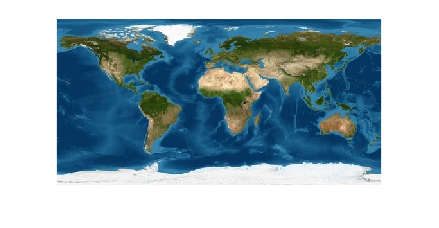

I = imread('mon1.jpg');
imshow(I);

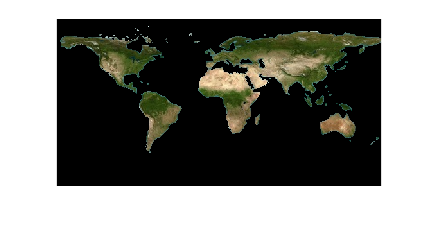

HSV = rgb2hsv(I);
H = HSV(:,:,1);
V = HSV(:,:,3);
H = (H < 0.5);
Vb = V.*H;
HSV(:,:,3) = Vb;

V = HSV(:,:,3);
S = HSV(:,:,2);
S = (S>0.1);
Vb = V.*S;
HSV(:,:,3) = Vb;
RGB = hsv2rgb(HSV);

imshow(RGB);